**Lab0**

**Objetivo: **determinar a frequência cardíaca a partir de um vídeo

**Passo 1: **ler o vídeo, criando um objeto de vídeo

video = VideoReader("ppg.mp4");

**Passo 2: **obtenção do sinal PPG

%vetor da dimensão do nr. de frames
signal = zeros(1,video.NumFrames); 
%iteração sobre cada frame
i=1;
while hasFrame(video)
    frame = readFrame(video);
    %média de todos os pixéis do canal vermelho (1)
    signal(i) = mean(frame(:,:,1),'all');
    i=i+1;
end

**Passo 3: **visualização do sinal PPG

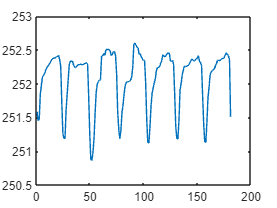

plot(signal)

**Passo 4: **cálculo do ritmo cardíaco

%máximos locais do sinal
[pks, locs] = findpeaks(signal)

'findpeaks' requires Signal Processing Toolbox.

%display results
figure
plot(signal,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

%plot local maxima
plot(find(maxIndices),signal(maxIndices),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices))
hold off
legend